close all; clear; clc;
dbstop if error;


fname = fullfile('data','robot_arm.dat');
disp('Loading data...')

Loading data...


data = load(fname);
u = data(:,1); y = data(:,2); t = (1:length(u))';
sf = 2;  % split factor
ut = u(1:end*(1-1/sf)); yt = y(1:end*(1-1/sf)); tt = t(1:end*(1-1/sf));
uv = u(end*(1-1/sf)+1:end); yv = y(end*(1-1/sf)+1:end); tv = t(end*(1-1/sf)+1:end);
clear fname;


% % Understanding data
disp('Understanding the data')

Understanding the data


disp('Plotting the input and the output signals...')

Plotting the input and the output signals...


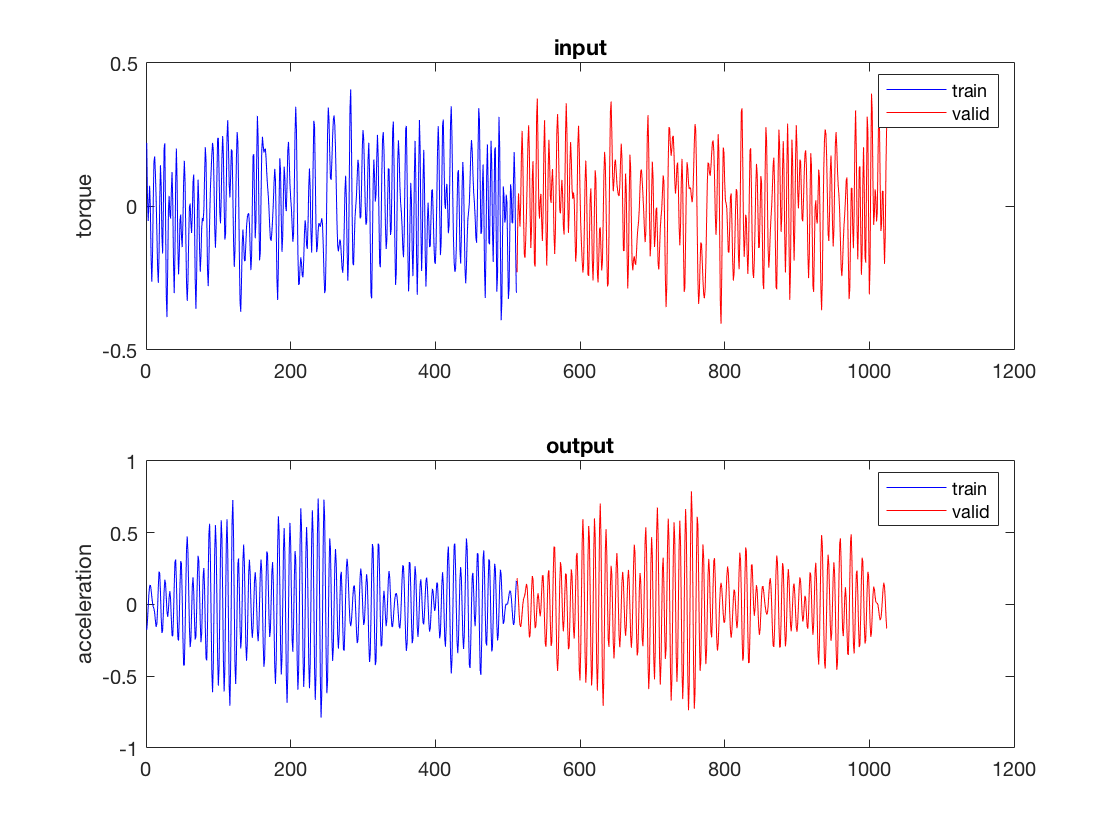

figure
subplot(2,1,1); plot(tt, ut, 'b'); hold on; plot(tv,uv,'r'); 
ylabel('torque'); title('input'); legend('train','valid');
subplot(2,1,2); plot(tt, yt, 'b'); hold on; plot(tv, yv,'r'); 
ylabel('acceleration');title('output'); legend('train','valid');


disp('Plotting the Empirical Transfer Function Estimate of training and validation data...')

Plotting the Empirical Transfer Function Estimate of training and validation data...


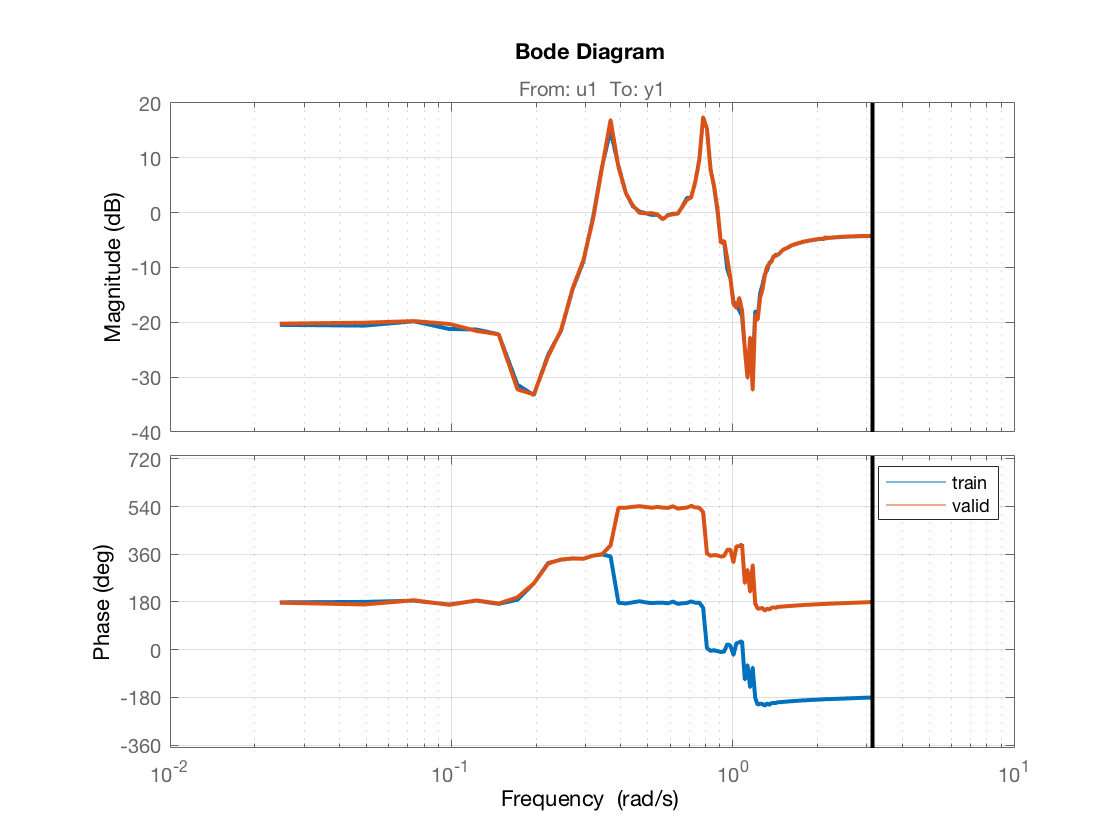

Ts = 1;  % I dont know about this value!
zt = iddata(yt, ut, Ts);  % training data
zv = iddata(yv, uv, Ts);  % validation data
ge_t = etfe(zt);
ge_v = etfe(zv);
figure; 
bode(ge_t, ge_v); legend('train','valid'); grid on;
set(findall(gcf,'type','line'),'linewidth',2)


% auto- and cross-correlation
%correlations(u, y)

%% Model fitting
model_handles = {@arx, @oe, @n4sid, @ssest, @tfest};
k = 5;
[models, mses, freeParams, akaikePre] = modelOrderVsFreeParams(model_handles, zt, zv, 10, k);

Model order 1 for arx
Model order 1 for oe
Model order 1 for n4sid
Model order 1 for ssest
Model order 1 for tfest
Model order 2 for arx
Model order 2 for oe
Model order 2 for n4sid
Model order 2 for ssest
Model order 2 for tfest
Model order 3 for arx
Model order 3 for oe
Model order 3 for n4sid
Model order 3 for ssest
Model order 3 for tfest
Model order 4 for arx
Model order 4 for oe
Model order 4 for n4sid
Model order 4 for ssest
Model order 4 for tfest
Model order 5 for arx
Model order 5 for oe
Model order 5 for n4sid
Model order 5 for ssest
Model order 5 for tfest
Model order 6 for arx
Model order 6 for oe
Model order 6 for n4sid
Model order 6 for ssest
Model order 6 for tfest
Model order 7 for arx
Model order 7 for oe
Model order 7 for n4sid
Model order 7 for ssest
Model order 7 for tfest
Model order 8 for arx
Model order 8 for oe
Model order 8 for n4sid
Model order 8 for ssest
Model order 8 for tfest
Model order 9 for arx
Model order 9 for oe
Model order 9 for n4sid
Model order 9

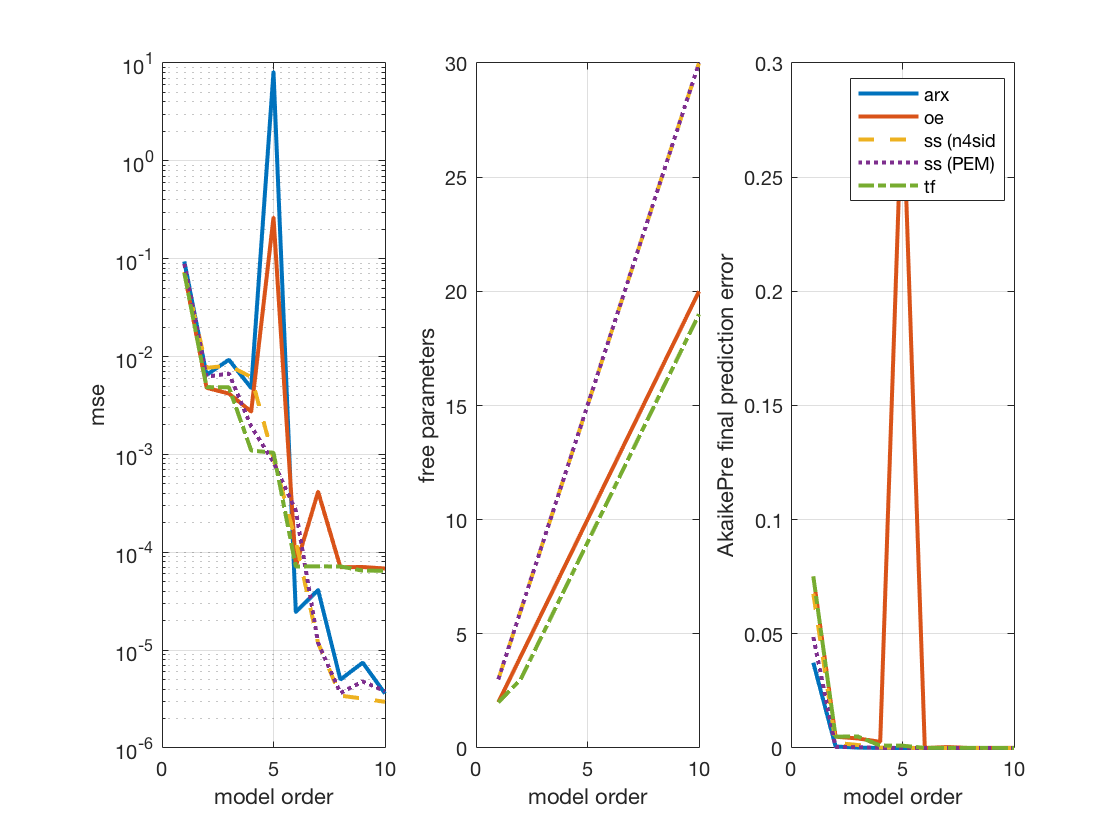


figure;
NameArray = {'LineStyle'};
ValueArray = {'-','-','--',':','-.'}';
subplot(1,4,1); p1 = semilogy(mses,'Linewidth',2); ylabel('mse'); xlabel('model order'); grid on
set(p1,NameArray,ValueArray)
subplot(1,4,2); p2 = plot(freeParams,'Linewidth',2); ylabel('free parameters'); xlabel('model order'); grid on
set(p2,NameArray,ValueArray)
subplot(1,4,3); p3 = semilogy(akaikePre,'Linewidth',2); ylabel('Final prediction error'); xlabel('model order'); grid on
set(p3,NameArray,ValueArray)
subplot(1,4,4); p4 = plot(akaikeIC,'Linewidth',2); ylabel('AkaikePre information criterion'); xlabel('model order'); grid on
set(p4,NameArray,ValueArray)
legend('arx', 'oe', 'ss (n4sid', 'ss (PEM)', 'tf')



%%
disp('pzmaps...')

pzmaps...


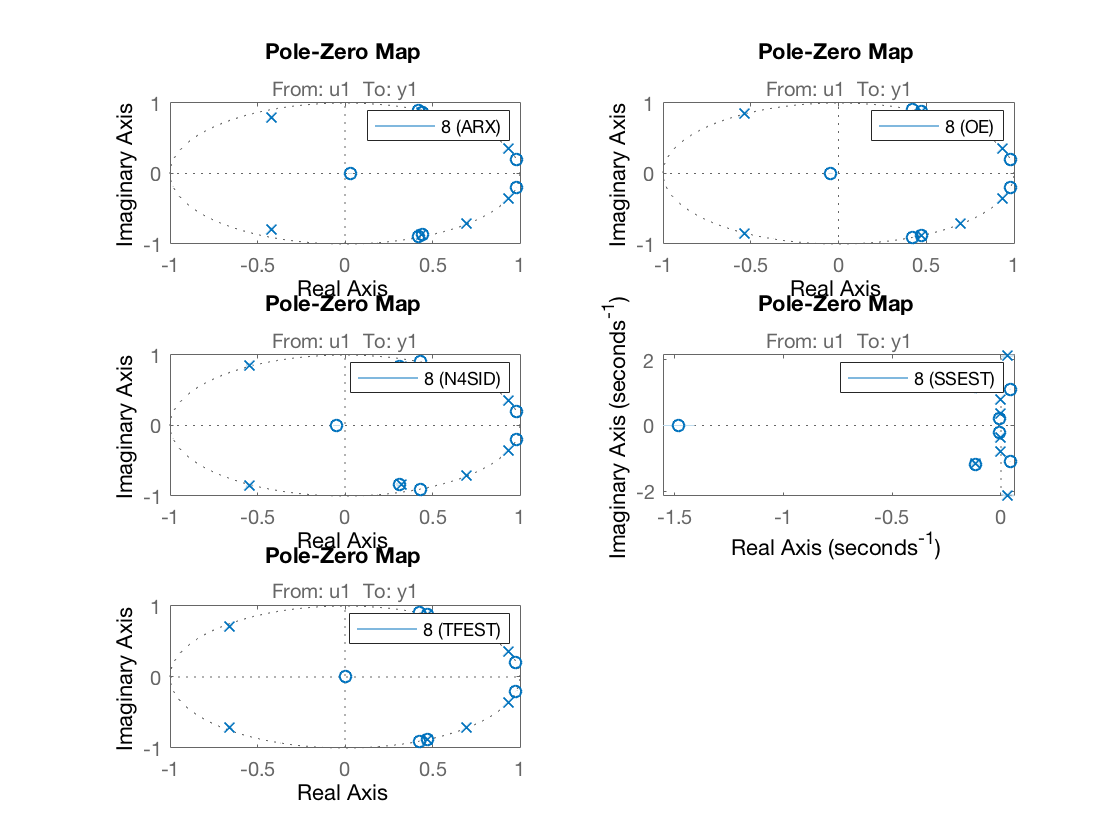

pzplots(models, 8)

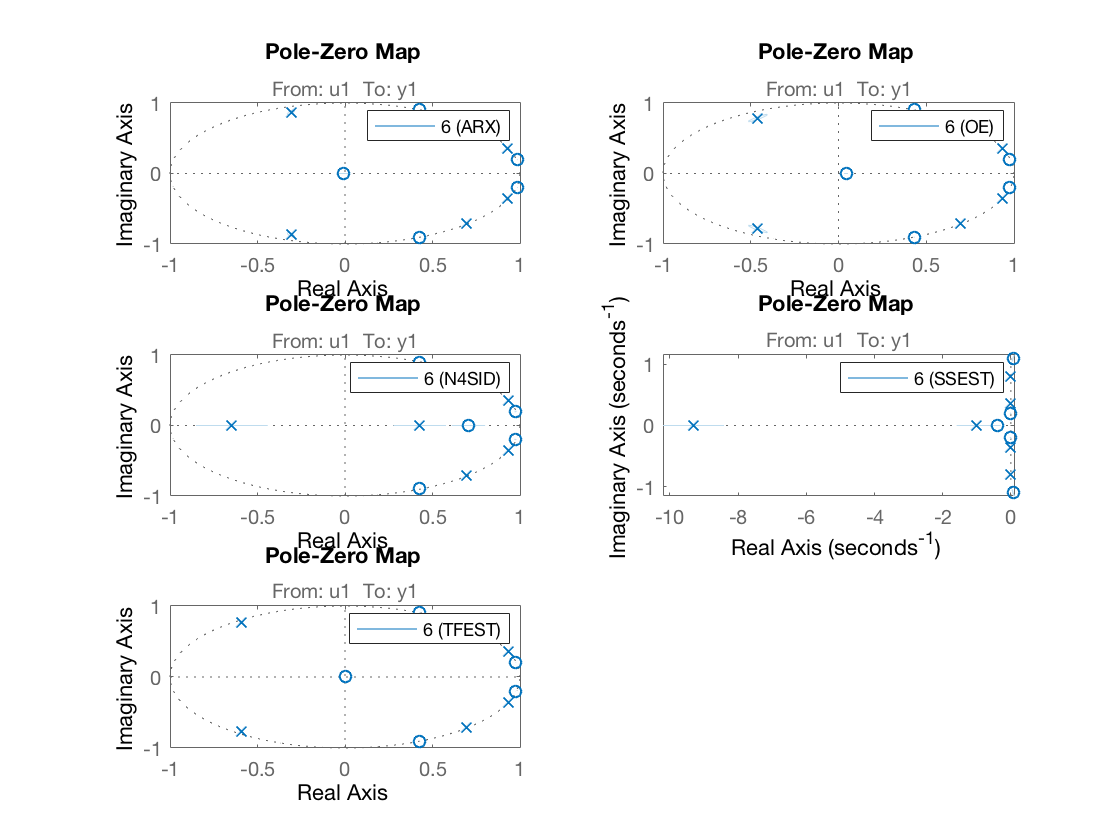


pzplots(models{1}, 6)


%%
disp('Nyquist plot...')

Nyquist plot...


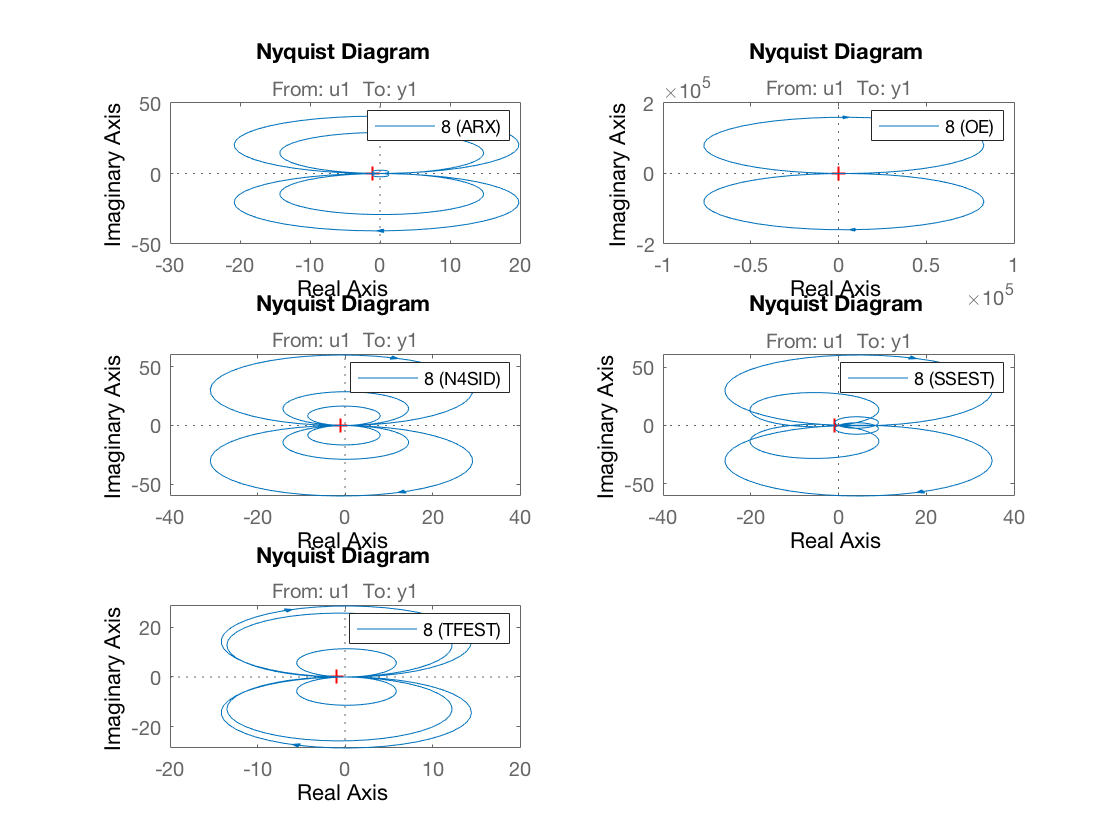

nyquistplots(models, 8)

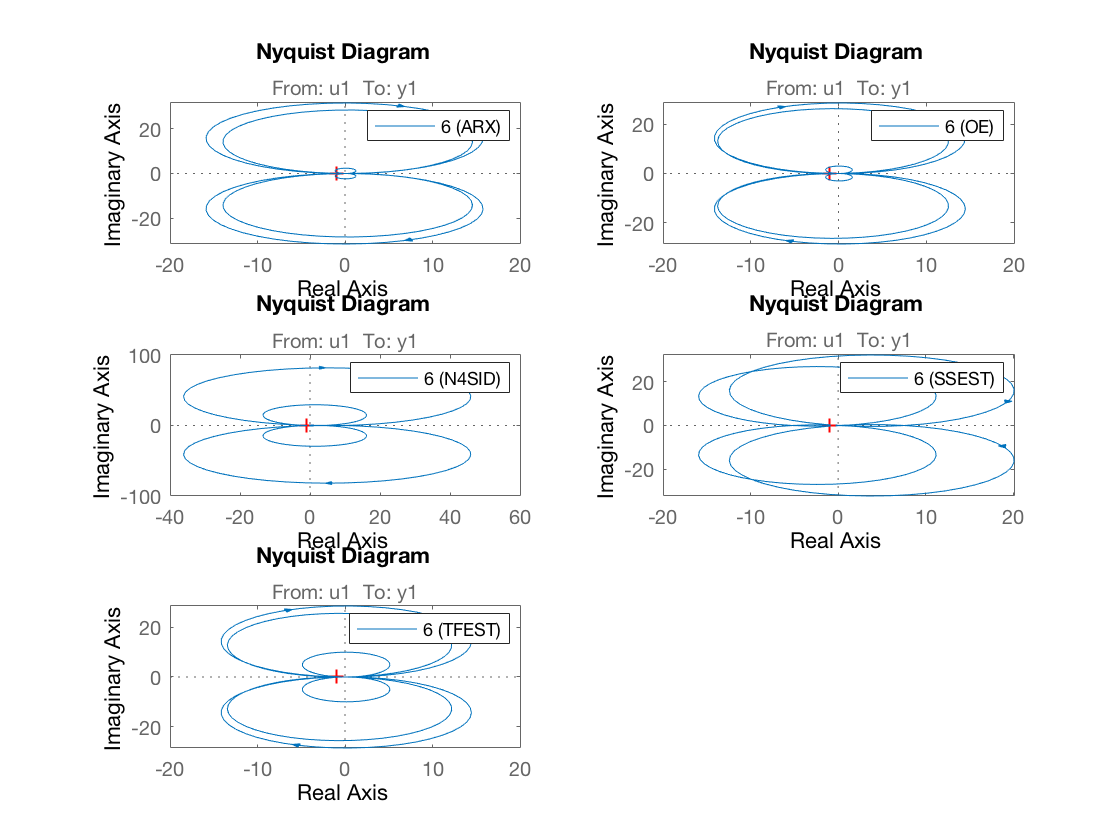


nyquistplots(models, 6)


%%
disp('Bode plots...')

Bode plots...


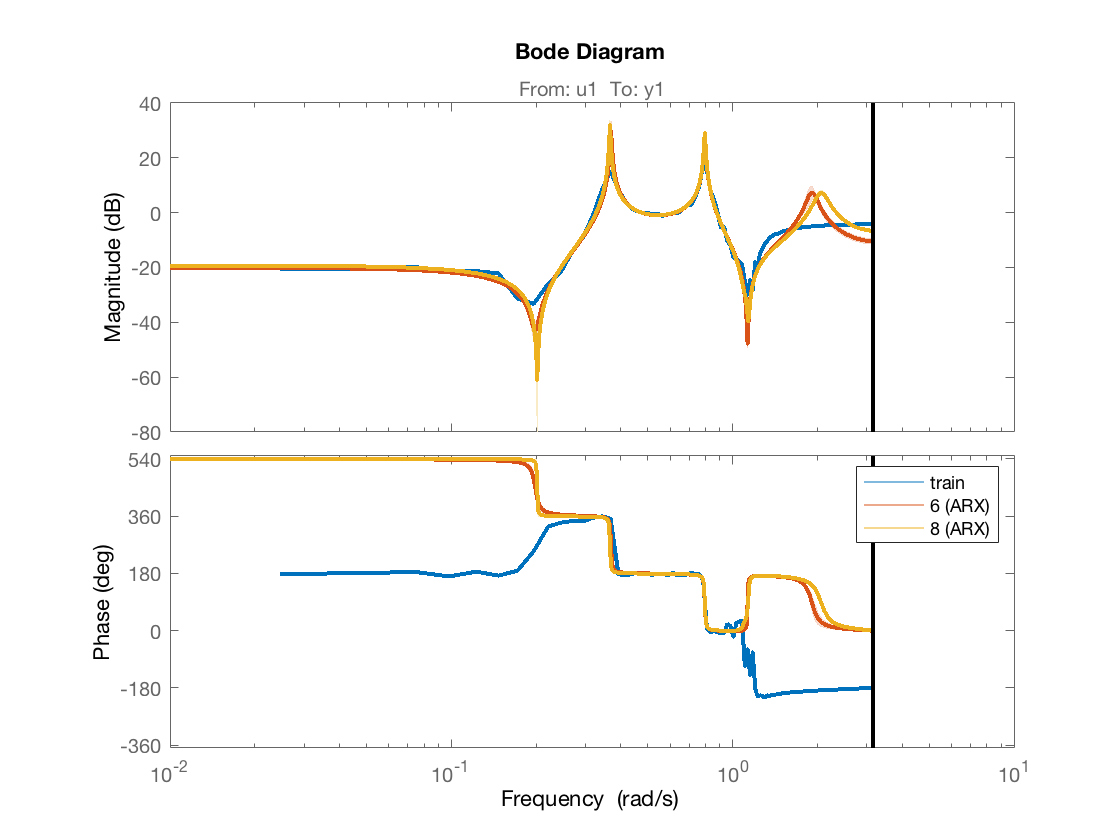

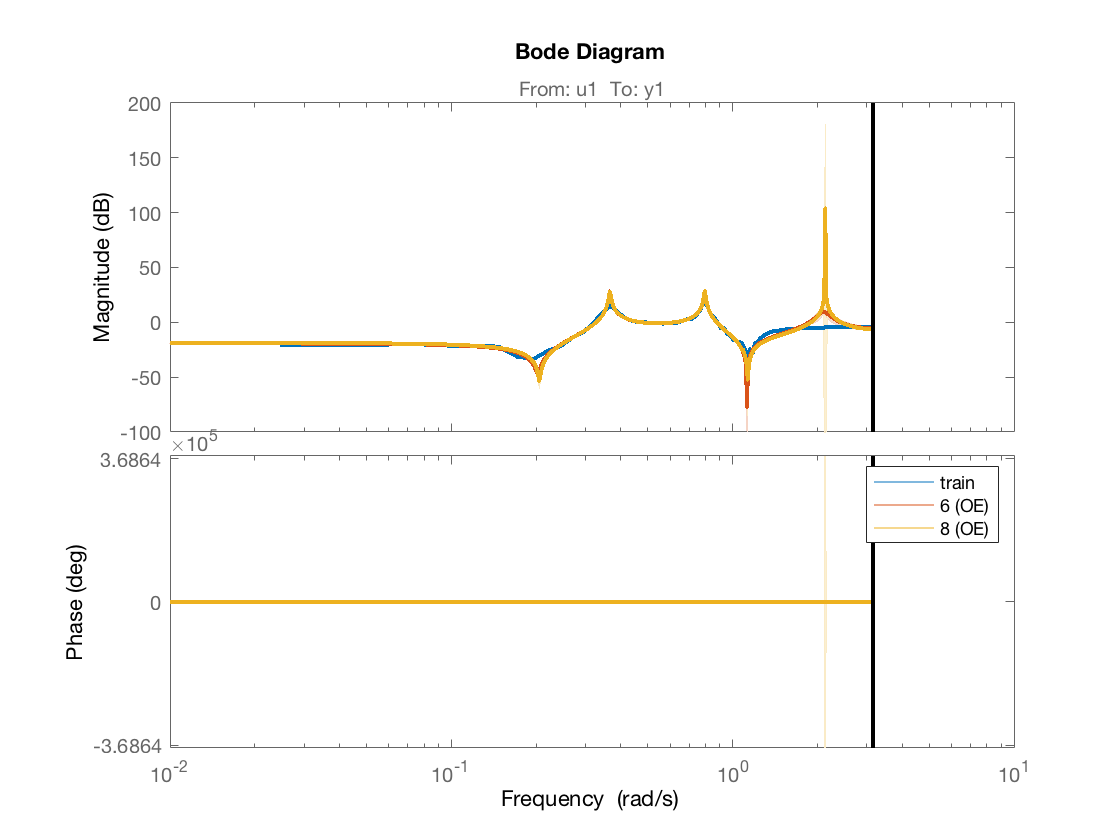

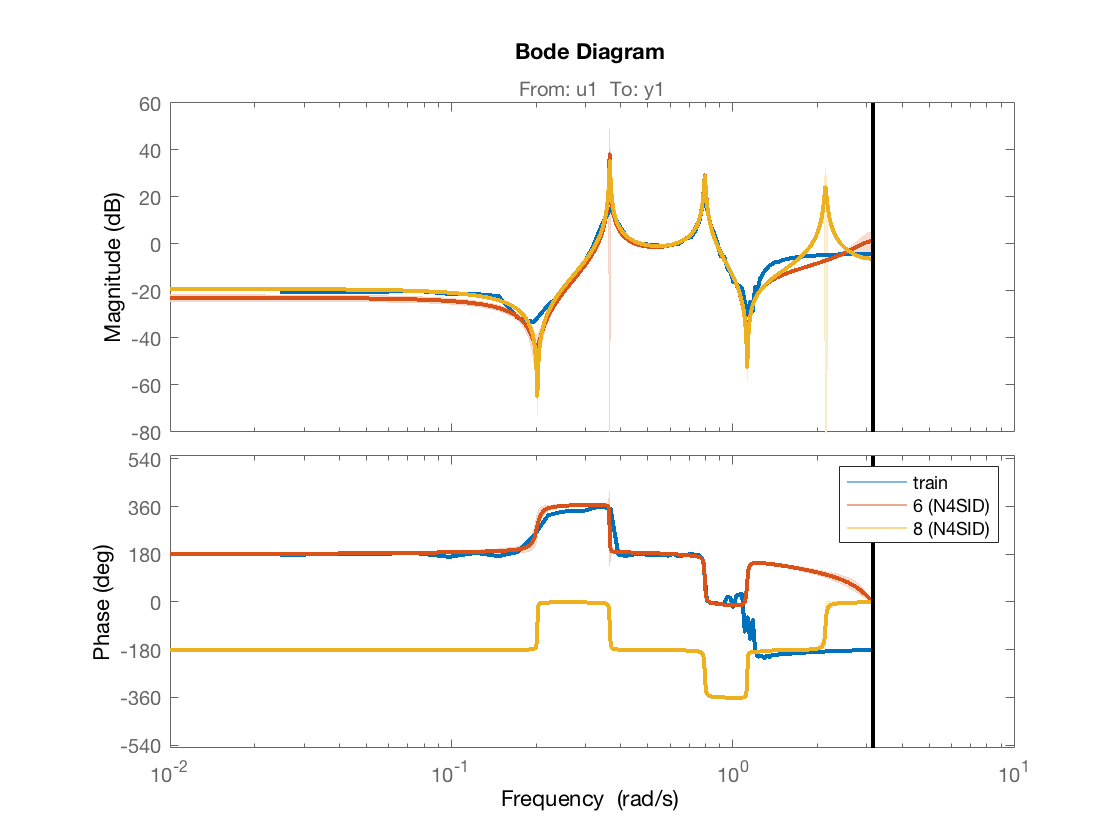

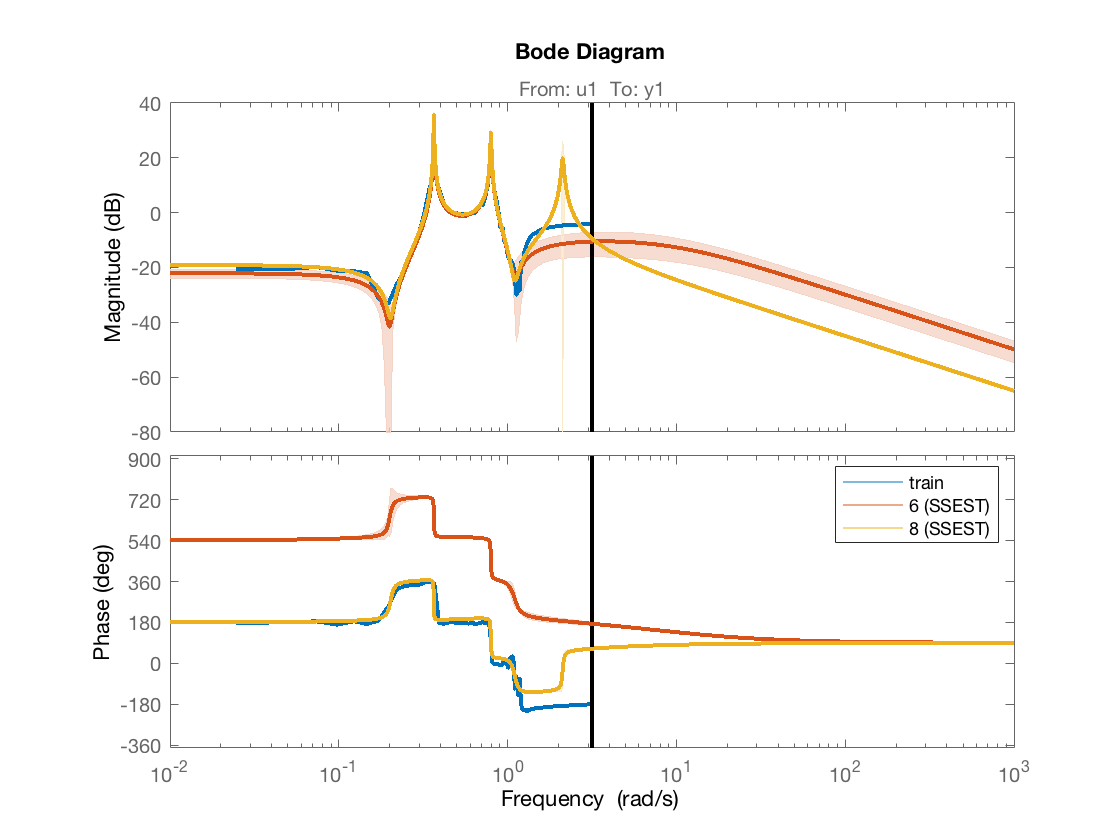

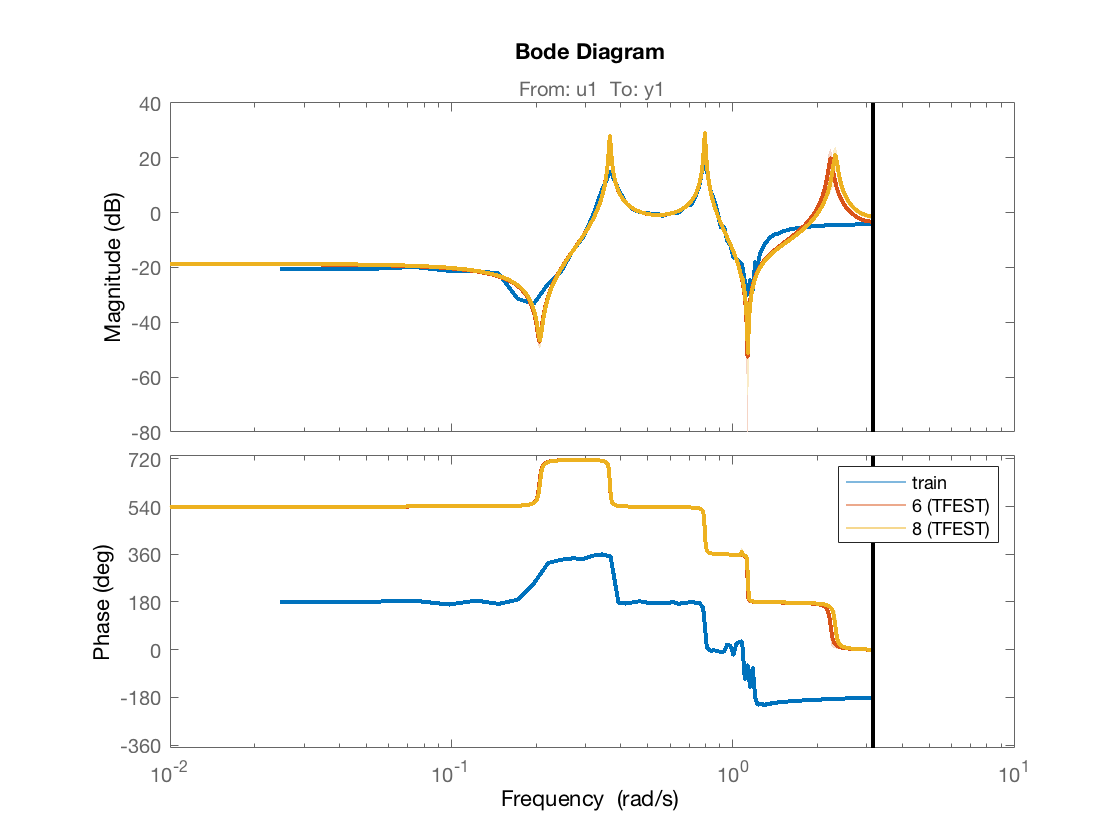

bode_plots(models, [6, 8], ge_t)


%%
disp('Simulations')

Simulations


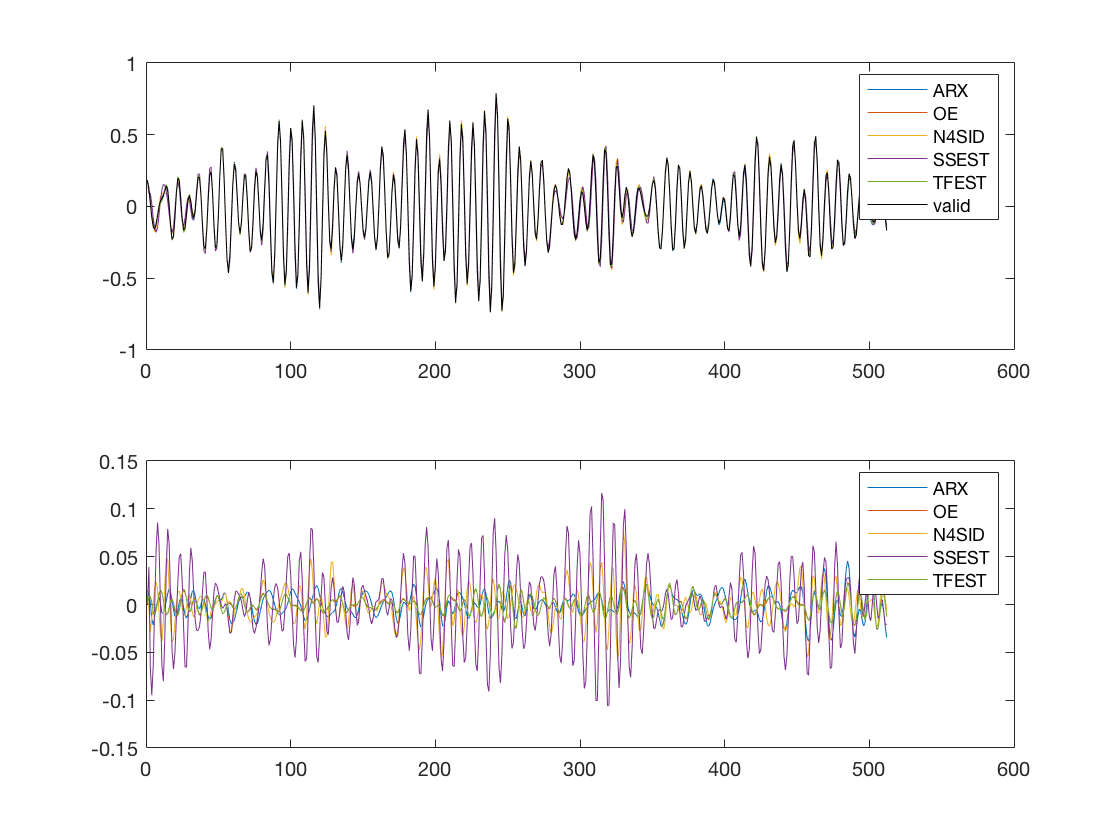

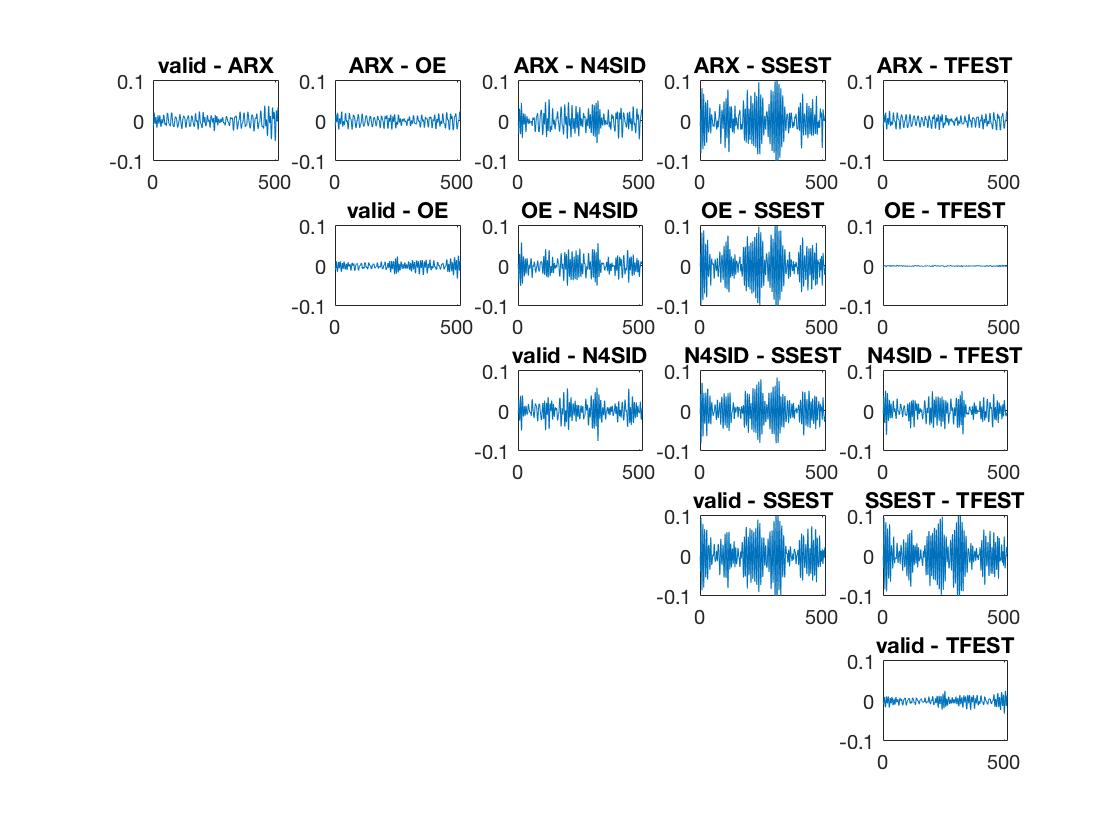

model_order = 6;
peplot(models, model_order, zv, inf)


disp('Predicions')

Predicions


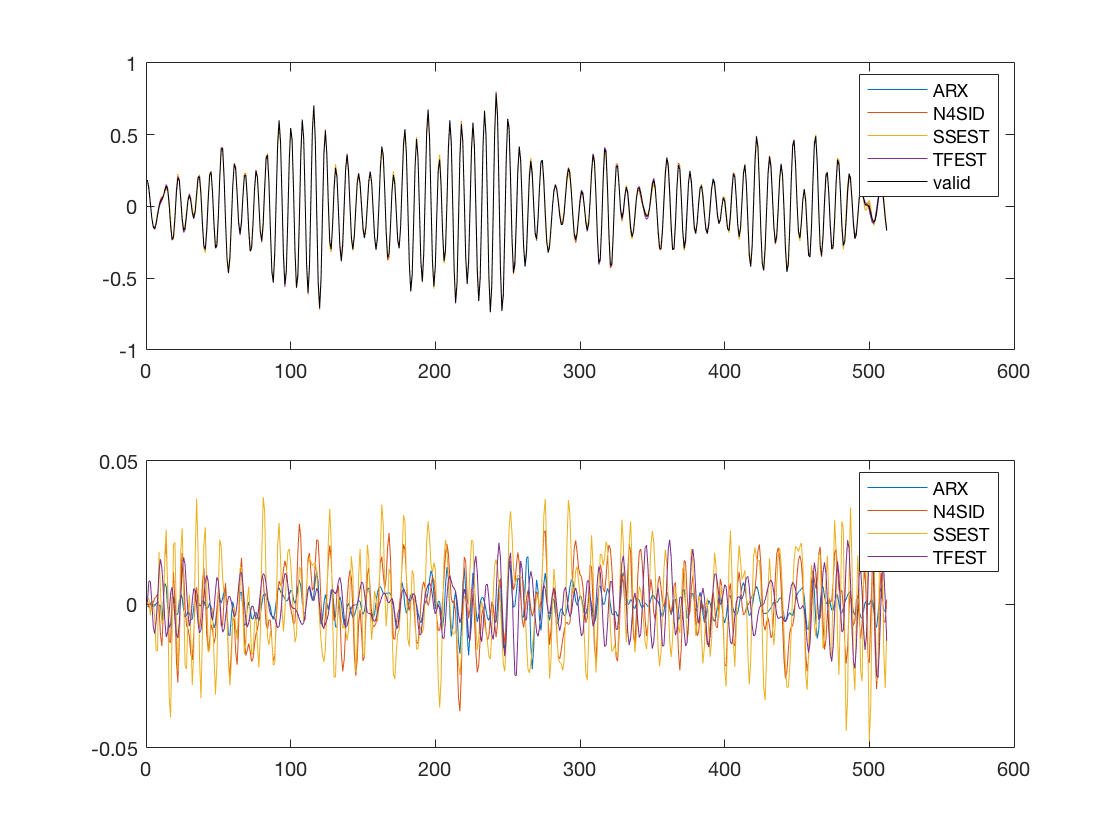

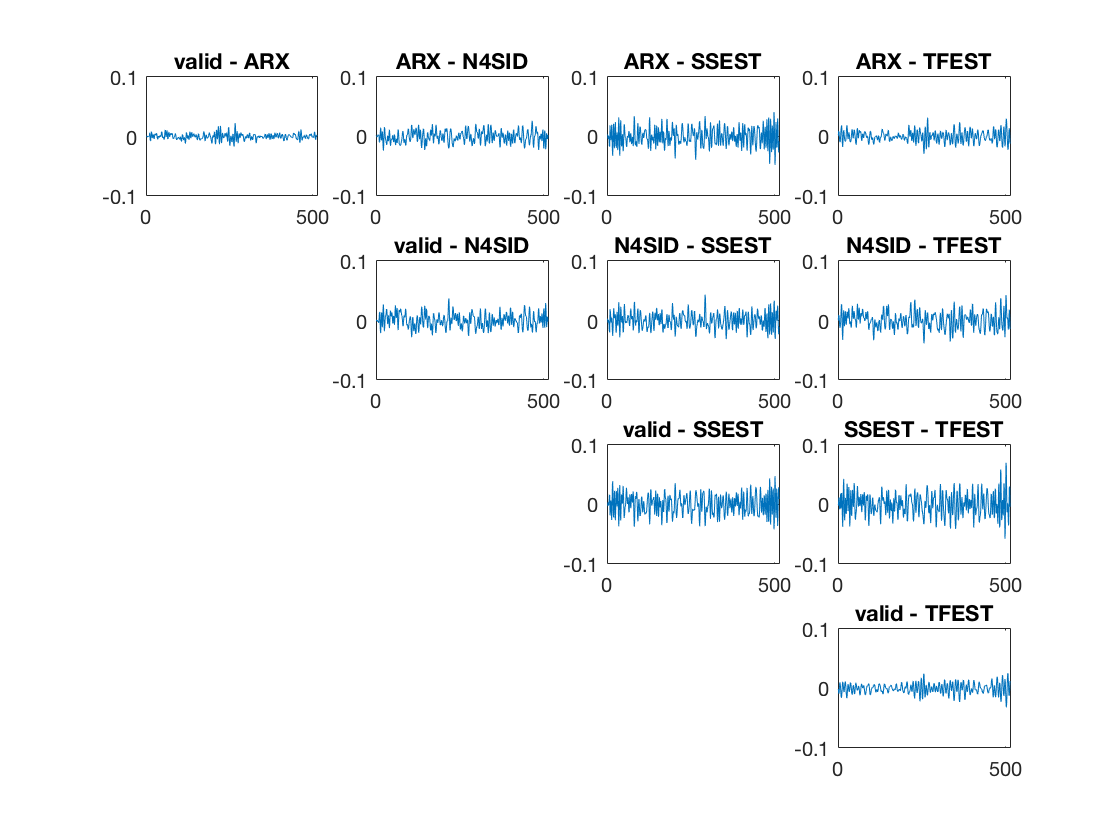

model_order = 6;
k = 5;
models_idx = cell2mat(cellfun(@(x) ~isequal(x,@oe), model_handles, 'UniformOutput', false));
peplot(models(:,models_idx), model_order, zv, k)


%%
disp('Residual Analysis')

Residual Analysis


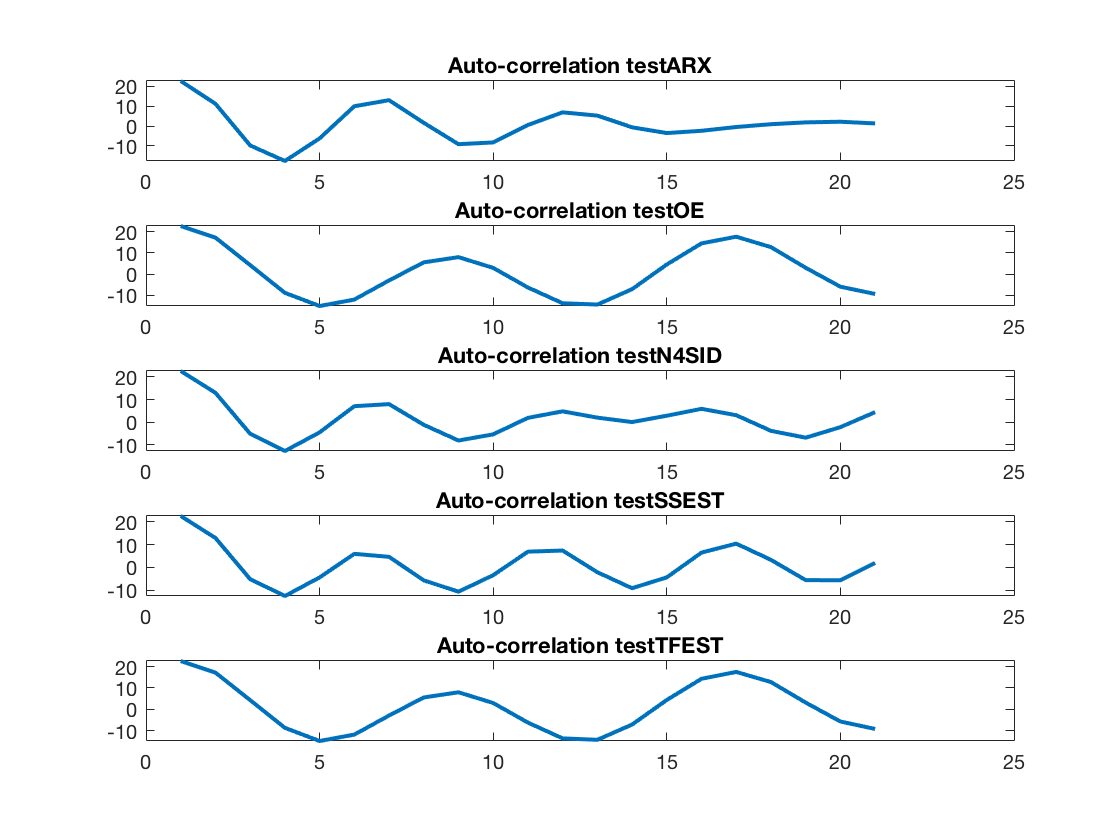

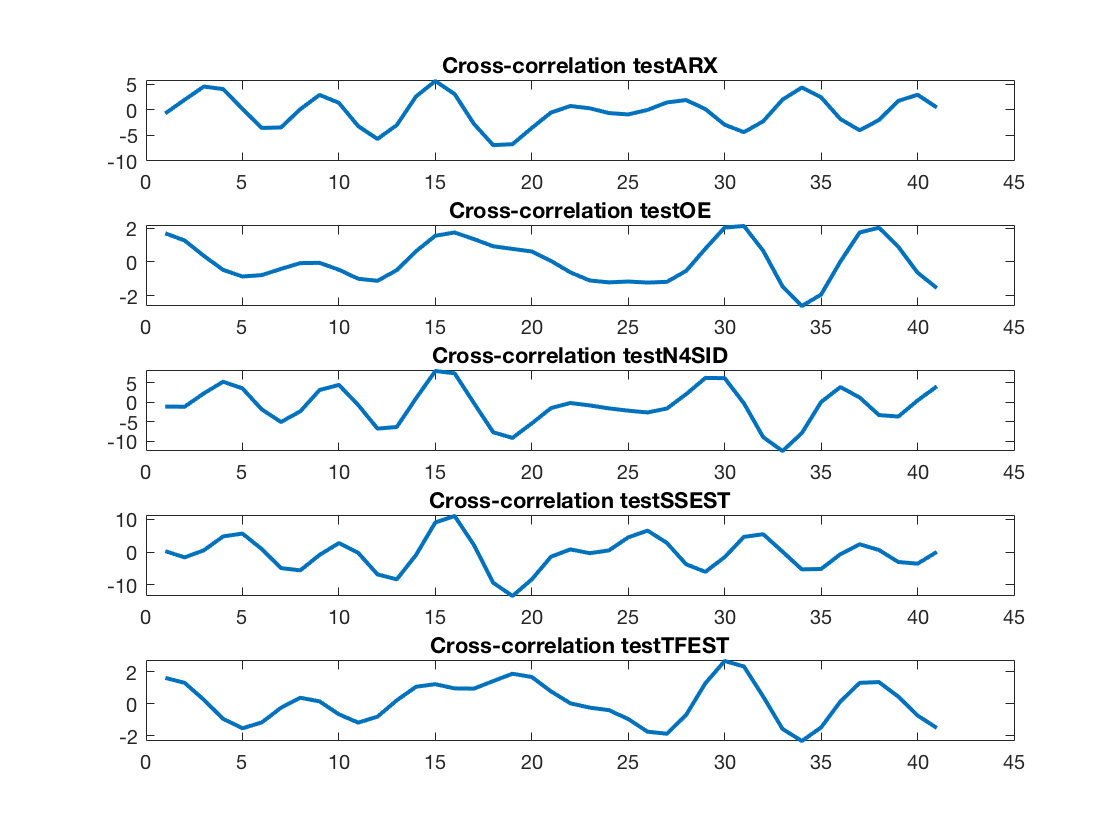

model_order = 6;
residualAnalysis_plot(models, model_order, zv, 1)

%%
disp('Nonlinear Identification')

Nonlinear Identification


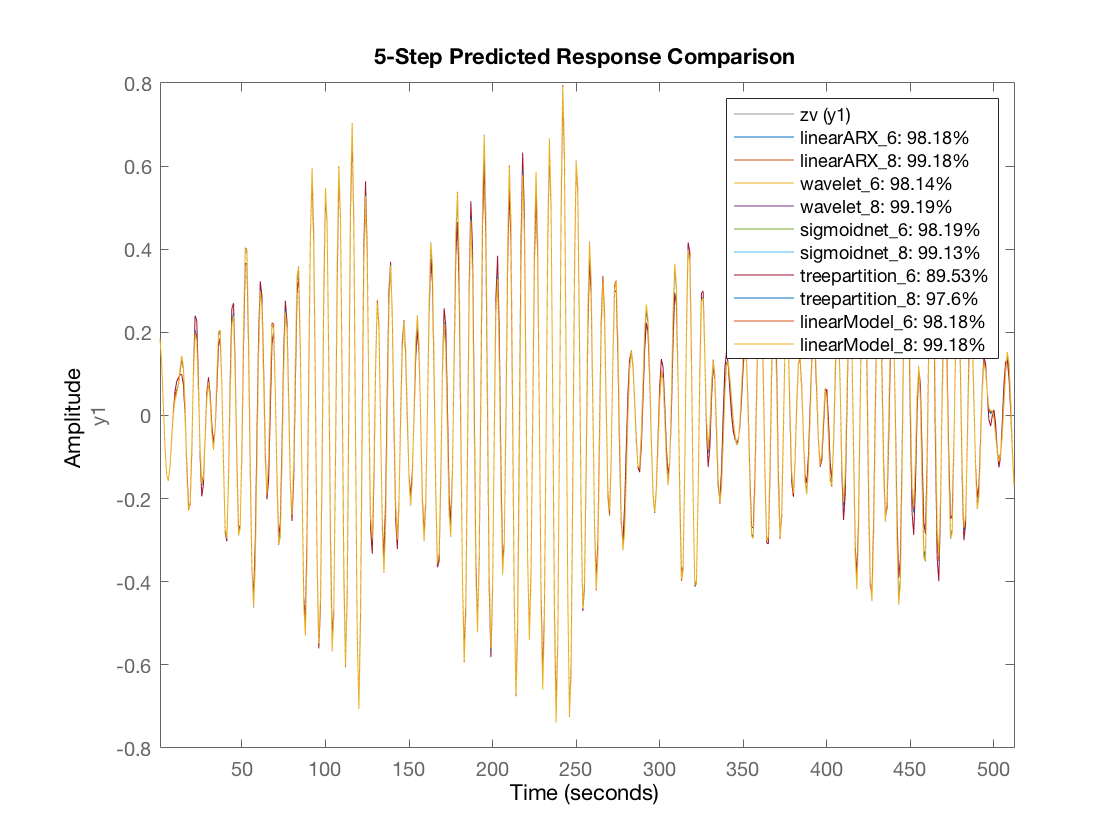

NL = wavenet('NumberOfUnits',5);
wavelet_6 = nlarx(zt,[6 6 1],NL);
wavelet_8 = nlarx(zt,[8 8 1],NL);
NL = sigmoidnet('NumberOfUnits',5);
sigmoidnet_6 = nlarx(zt,[6 6 1],NL);
sigmoidnet_8 = nlarx(zt,[8 8 1],NL);
NL = treepartition('NumberOfUnits',5);
treepartition_6 = nlarx(zt,[6 6 1],NL);
treepartition_8 = nlarx(zt,[8 8 1],NL);
linearARX_6 = arx(zt,[6 6 1]);
linearModel_6 = nlarx(zt,linearARX_6);
linearARX_8 = arx(zt,[8 8 1]);
linearModel_8 = nlarx(zt,linearARX_8);
figure
compare(zv, linearARX_6, linearARX_8, wavelet_6,wavelet_8,...
    sigmoidnet_6,sigmoidnet_8,treepartition_6,treepartition_8,linearModel_6,linearModel_8, 5);

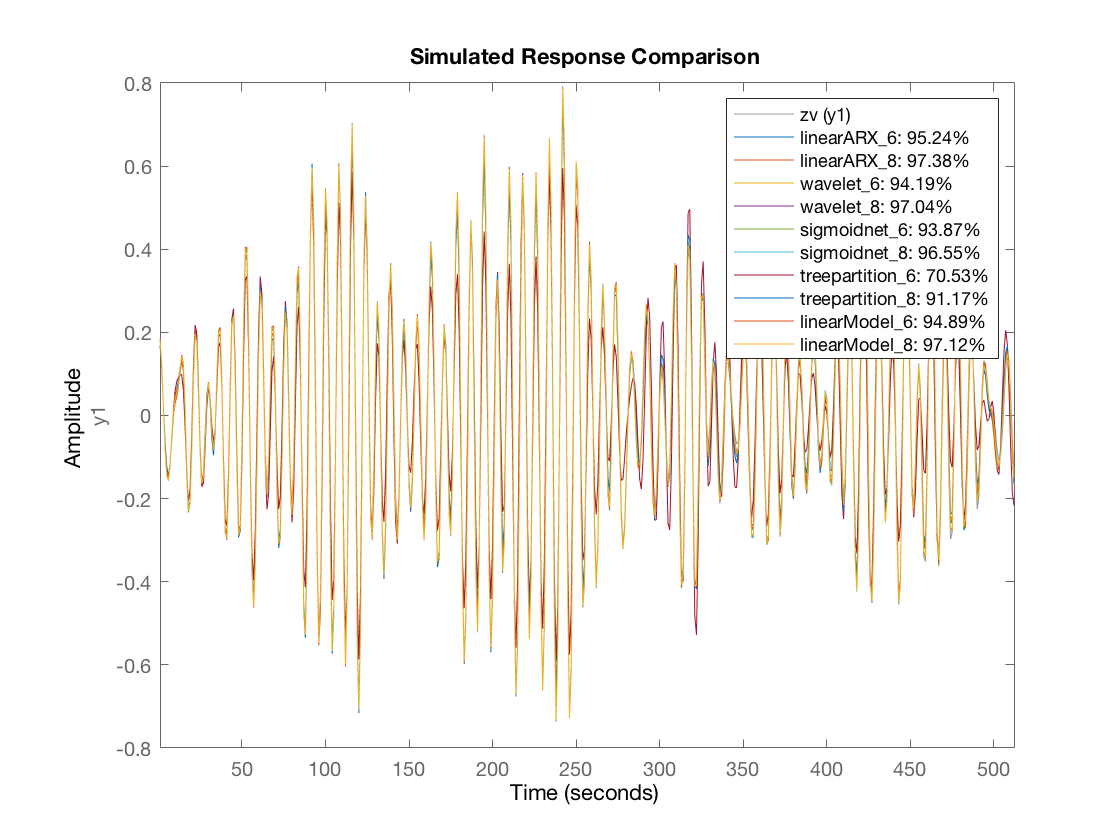

figure
compare(zv, linearARX_6, linearARX_8, wavelet_6,wavelet_8,...
    sigmoidnet_6,sigmoidnet_8,treepartition_6,treepartition_8,linearModel_6,linearModel_8, Inf);

function correlations(u_in, y_in)
    figure
    cv = 2/sqrt(length(u_in)); %critival value, using normal assumption
    subplot(2,2,1); autocorr(u_in, 'NumLags', 50); title('autocorr(u(t))')
    subplot(2,2,3); [r_yu, lags] = xcorr(y_in, u_in, 50, 'coeff'); stem(lags, r_yu, '.')
    hold on; plot(lags, cv*ones(size(lags)), 'k', lags, -cv*ones(size(lags)), 'k');
    title('xcorr(y(t), u(t))')
    subplot(2,2,4); autocorr(y_in, 'NumLags', 50); title('autocorr(y(t))')
end


function [trained_models, mses, freeParams, akaikePre] = modelOrderVsFreeParams(models, zt, zv, n, k)
    num_models = length(models);
    mses = zeros(n, num_models);
    akaikePre = zeros(n, num_models);
    freeParams = zeros(n, num_models);
    trained_models = cell(n, num_models);
    for ni=1:n
        for mi = 1:num_models
            model = models{mi};
            mfun = functions(model);
            fprintf('Model order %d for %s\n', ni, mfun.function);
            switch mfun.function
                case 'arx'
                    Opt = arxOptions;
                    ns = [ni ni 1];
                    opt_fun = @() model(zt, ns, Opt);
                case 'oe'
                    Opt = oeOptions;
                    ns = [ni ni 1];
                    Opt.Focus = 'simulation';
                    opt_fun = @() model(zt, ns, Opt);
                case 'n4sid'
                    Opt = n4sidOptions;       
%                     Opt.Display = 'on';
                    ns = ni;
                    opt_fun = @() model(zt, ns, 'Form', 'canonical', Opt);
                case 'ssest'
                    Opt = ssestOptions;       
%                     Opt.Display = 'on';     
                    ns = ni;
                    opt_fun = @() model(zt, ns, 'Form', 'canonical', Opt);
                case 'tfest'
                    Opt = tfestOptions;                   
%                     Opt.Display = 'on';                   
                    Opt.WeightingFilter = [];
                    ns = ni;
                    opt_fun = @() model(zt, ns, Opt, 'Ts', 1);
                otherwise
            end
            
            m = opt_fun();
            trained_models{ni, mi} = m;
            freeParams(ni, mi) = sum(m.Report.Parameters.Free);
            yp = predict(m, zv, k); % k-step prediction
            mse = immse(zv.y, yp.y); 
            mses(ni, mi) = mse;
            akaikePre(ni,mi) = m.Report.Fit.FPE;
        end
    end
end

function bode_plots(models, idxs, ge)
    [nrows, ncols] = size(models);
    rows = 1:nrows;
    for i = 1:ncols
        figure;
        leg = cell(1, length(idxs)+1);
        bode(ge); leg{1,1} = 'train'; hold on;
        for k = 1:length(idxs)
            idx = idxs(k);
            j = rows(idx);
            h = bodeplot(models{j,i});
            showConfidence(h, 0.95);
            leg{1, k+1} = strcat(int2str(idx),' (', models{1,i}.Report.method, ')');
        end
        legend(leg)
        set(findall(gcf,'type','line'),'linewidth',2)
    end
end

function pzplots(models, model_order)
    [nrows, ncols] = size(models);
    rows = 1:nrows;
    M = ceil(sqrt(ncols));
    figure;
    for i = 1:ncols
        subplot(M, ceil(ncols/M), i);
        j = rows(model_order);
        h = iopzplot(models{j,i});
        showConfidence(h, 0.95)
        legend(strcat(int2str(model_order),' (', models{1,i}.Report.method, ')'))
    end
end

function nyquistplots(models, model_order)
    [nrows, ncols] = size(models);
    rows = 1:nrows;
    M = ceil(sqrt(ncols));
    figure;
    for i = 1:ncols
        subplot(M, ceil(ncols/M), i);
        j = rows(model_order);
        h = nyquistplot(models{j,i});
%         showConfidence(h, 0.95)
        legend(strcat(int2str(model_order),' (', models{1,i}.Report.method, ')'))
    end
end

function peplot(models, model_order, zv, k)
    [nrows, ncols] = size(models);
    rows = 1:nrows;
    figure;
    leg1 = cell(1, ncols+1);
    leg2 = cell(1, ncols);
    P = zeros(ncols, length(zv.y));
    for i = 1:ncols
        j = rows(model_order);
        pred = predict(models{j,i}, zv, k);
        P(i, :) = pred.y;
        e = zv.y - pred.y;
        subplot(2,1,1); plot(pred.y); hold on;
        subplot(2,1,2); plot(e); hold on;
        leg1{1, i} = models{1,i}.Report.method;
        leg2{1, i} = models{1,i}.Report.method;
    end
    subplot(2,1,1); plot(zv.y, 'k'); hold on; leg1{1,end} = 'valid';
    subplot(2,1,1); legend(leg1);
    subplot(2,1,2); legend(leg2);
    figure
    for i = 1:ncols
        for j = i:ncols
            subplot(ncols, ncols, (i-1)*ncols+j)
            if i == j
                plot(P(i,:) - zv.y')
                title(sprintf('valid - %s',models{1,i}.Report.method))
            else
                plot(P(i,:)-P(j,:))
                title(sprintf('%s - %s',models{1,i}.Report.method,models{1,j}.Report.method))
            end
        ylim([-0.1 0.1])    
            
        end
    end
end

function residualAnalysis_plot(models, model_order, zv, k)
    [nrows, ncols] = size(models);
    rows = 1:nrows;
    figure;
    P = zeros(ncols, length(zv.y));
    for i = 1:ncols
        j = rows(model_order);
        pred = predict(models{j,i}, zv, k);
        P(i, :) = pred.y;
        e = zv.y - pred.y;
        acv = autocorr(e); acv = acv/acv(1)*sqrt(length(e));
        subplot(ncols,1,i); plot(acv,'Linewidth',2); title(strcat('Auto-correlation test ',models{1,i}.Report.method));
    end
    figure;
    for i = 1:ncols
        j = rows(model_order);
        pred = predict(models{j,i}, zv, k);
        P(i, :) = pred.y;
        e = zv.y - pred.y;
        acve = autocorr(e);
        acvu = autocorr(zv.u);
        ccv = crosscorr(zv.u,e); ccv = ccv*sqrt(length(e))/sqrt(acve(1)*acvu(1));
        subplot(ncols,1,i); plot(ccv,'Linewidth',2); title(strcat('Cross-correlation test ',models{1,i}.Report.method));
    end
end

